# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                        ex5_companion.mlx        learningCurve.asv        plotFit.m                trainLinearReg.m         
..                       ex5data1.mat             learningCurve.m          polyFeatures.m           validationCurve.m        
.MATLABDriveTag          featureNormalize.m       lib                      submit.m                 
ex5.mlx                  fmincg.m                 linearRegCostFunction.m  token.mat                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

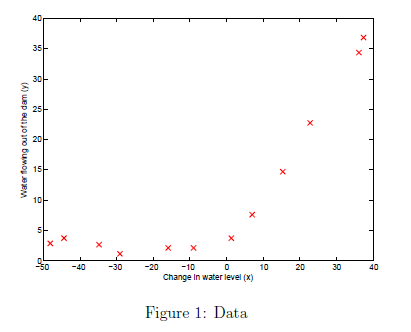

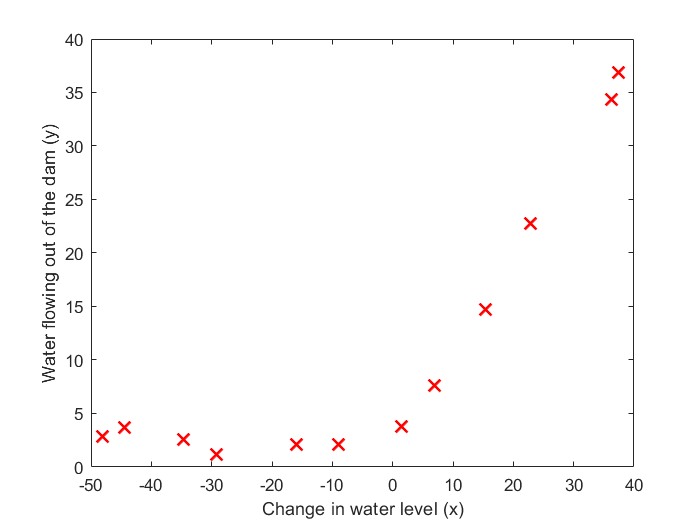

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overfitting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Cost at theta = [1 ; 1]: 303.993192

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01


    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

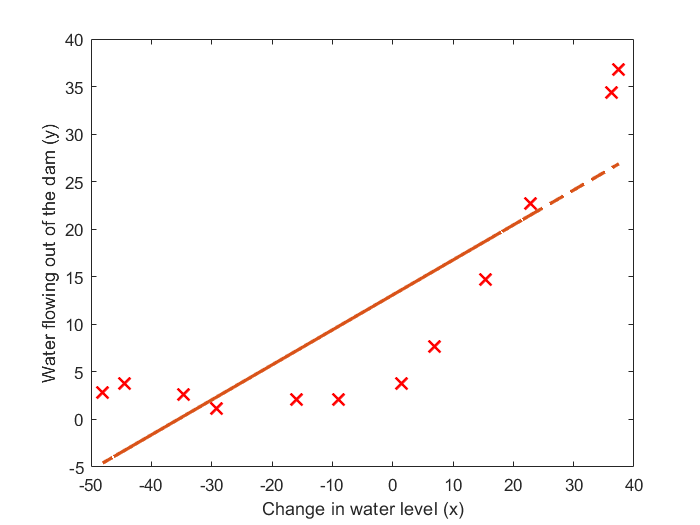

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

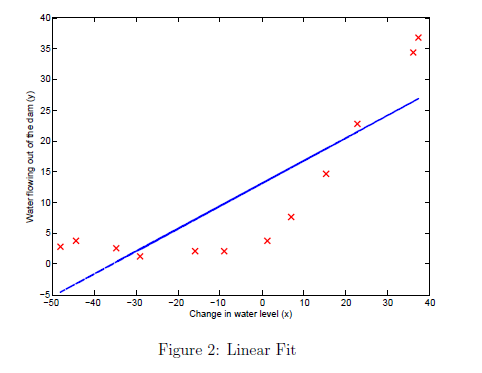

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

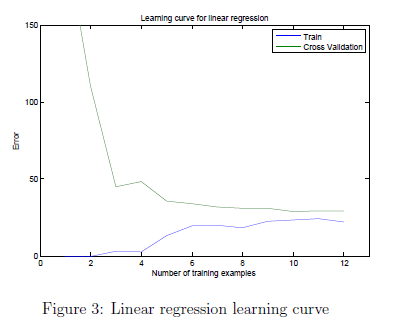

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00


theta =     0.0084
   -0.1334


Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32


theta =     3.2932
    0.0727


Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00


theta =    14.1550
    0.5391


Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.843147e+00
Iteration     7 | Cost: 2.842791e+00
Iteration     8 | Cost: 2.842765e+00
Iteration     9 | Cost: 2.842679e+00
Iteration    10 | Cost: 2.842679e+00
Iteration    11 | Cost: 2.842679e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration    14 | Cost: 2.842678e+00
Iteration    15 | Cost: 2.842678e+00
Iteration    16 | Cost: 2.842678e+00
Iteration    17 | Cost: 2.842678e+00
Iteration    18 | Cost: 2.842678e+00
Iteration    19 | Cost: 2.842678e+00
Iteration    20 | Cost: 2.842678e+00
Iteration    21 | Cost: 2.842678e+00
Iteration    22 | Cost: 2.842678e+00
Iteration    23 | Cost: 2.842678e+00
Iteration    24 | Cost: 2.842678e+00
Iteration    25 | Cost: 2.842678e+00
Iteration    26 | Cost: 2.842678e+00
Iteration    27 | Cost: 2.842678e+00
I

theta =    14.6243
    0.5599


Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
Iteration     8 | Cost: 1.475292e+01
Iteration     9 | Cost: 1.430565e+01
Iteration    10 | Cost: 1.388881e+01
Iteration    11 | Cost: 1.327330e+01
Iteration    12 | Cost: 1.323519e+01
Iteration    13 | Cost: 1.319411e+01
Iteration    14 | Cost: 1.317355e+01
Iteration    15 | Cost: 1.315411e+01
Iteration    16 | Cost: 1.315405e+01
Iteration    17 | Cost: 1.315405e+01
Iteration    18 | Cost: 1.315405e+01
Iteration    19 | Cost: 1.315405e+01
Iteration    20 | Cost: 1.315405e+01
Iteration    21 | Cost: 1.315405e+01
Iteration    22 | Cost: 1.315405e+01


theta =    17.2138
    0.4497


Iteration     1 | Cost: 1.531141e+02
Iteration     2 | Cost: 1.350947e+02
Iteration     3 | Cost: 1.137334e+02
Iteration     4 | Cost: 4.404199e+01
Iteration     5 | Cost: 2.957435e+01
Iteration     6 | Cost: 2.719561e+01
Iteration     7 | Cost: 1.949283e+01
Iteration     8 | Cost: 1.949128e+01
Iteration     9 | Cost: 1.945708e+01
Iteration    10 | Cost: 1.944472e+01
Iteration    11 | Cost: 1.944472e+01
Iteration    12 | Cost: 1.944471e+01
Iteration    13 | Cost: 1.944453e+01
Iteration    14 | Cost: 1.944425e+01
Iteration    15 | Cost: 1.944411e+01
Iteration    16 | Cost: 1.944396e+01
Iteration    17 | Cost: 1.944396e+01
Iteration    18 | Cost: 1.944396e+01
Iteration    19 | Cost: 1.944396e+01
Iteration    20 | Cost: 1.944396e+01
Iteration    21 | Cost: 1.944396e+01
Iteration    22 | Cost: 1.944396e+01
Iteration    23 | Cost: 1.944396e+01
Iteration    24 | Cost: 1.944396e+01
Iteration    25 | Cost: 1.944396e+01
Iteration    26 | Cost: 1.944396e+01
Iteration    27 | Cost: 1.944396e+01
I

theta =    15.4049
    0.4574


Iteration     1 | Cost: 1.383936e+02
Iteration     2 | Cost: 1.210275e+02
Iteration     3 | Cost: 1.013004e+02
Iteration     4 | Cost: 3.457729e+01
Iteration     5 | Cost: 2.808710e+01
Iteration     6 | Cost: 2.732288e+01
Iteration     7 | Cost: 2.011513e+01
Iteration     8 | Cost: 2.011508e+01
Iteration     9 | Cost: 2.010693e+01
Iteration    10 | Cost: 2.010640e+01
Iteration    11 | Cost: 2.010629e+01
Iteration    12 | Cost: 2.010382e+01
Iteration    13 | Cost: 2.009852e+01
Iteration    14 | Cost: 2.009852e+01
Iteration    15 | Cost: 2.009852e+01
Iteration    16 | Cost: 2.009852e+01
Iteration    18 | Cost: 2.009852e+01


theta =    14.2668
    0.4368


Iteration     1 | Cost: 1.237772e+02
Iteration     2 | Cost: 1.202532e+02
Iteration     3 | Cost: 1.195134e+02
Iteration     4 | Cost: 9.334231e+01
Iteration     5 | Cost: 4.813526e+01
Iteration     6 | Cost: 2.616064e+01
Iteration     7 | Cost: 1.894629e+01
Iteration     8 | Cost: 1.825637e+01
Iteration     9 | Cost: 1.823371e+01
Iteration    10 | Cost: 1.822191e+01
Iteration    11 | Cost: 1.817667e+01
Iteration    12 | Cost: 1.817653e+01
Iteration    13 | Cost: 1.817549e+01
Iteration    14 | Cost: 1.817286e+01
Iteration    15 | Cost: 1.817286e+01
Iteration    16 | Cost: 1.817286e+01
Iteration    18 | Cost: 1.817286e+01


theta =    14.6234
    0.4231


Iteration     1 | Cost: 1.089984e+02
Iteration     2 | Cost: 1.064701e+02
Iteration     3 | Cost: 1.054742e+02
Iteration     4 | Cost: 2.266786e+01
Iteration     5 | Cost: 2.266786e+01
Iteration     6 | Cost: 2.266758e+01
Iteration     7 | Cost: 2.260941e+01
Iteration     9 | Cost: 2.260941e+01


theta =    13.2966
    0.4130


Iteration     1 | Cost: 1.108611e+02
Iteration     2 | Cost: 2.497543e+01
Iteration     3 | Cost: 2.496421e+01
Iteration     4 | Cost: 2.494838e+01
Iteration     5 | Cost: 2.493176e+01
Iteration     6 | Cost: 2.490651e+01
Iteration     7 | Cost: 2.474387e+01
Iteration     8 | Cost: 2.326170e+01
Iteration     9 | Cost: 2.326170e+01
Iteration    10 | Cost: 2.326166e+01
Iteration    11 | Cost: 2.326146e+01
Iteration    12 | Cost: 2.326146e+01
Iteration    13 | Cost: 2.326146e+01
Iteration    14 | Cost: 2.326146e+01
Iteration    15 | Cost: 2.326146e+01
Iteration    16 | Cost: 2.326146e+01
Iteration    17 | Cost: 2.326146e+01
Iteration    18 | Cost: 2.326146e+01
Iteration    19 | Cost: 2.326146e+01
Iteration    20 | Cost: 2.326146e+01
Iteration    21 | Cost: 2.326146e+01
Iteration    22 | Cost: 2.326146e+01
Iteration    23 | Cost: 2.326146e+01
Iteration    24 | Cost: 2.326146e+01
Iteration    25 | Cost: 2.326146e+01
Iteration    26 | Cost: 2.326146e+01
Iteration    27 | Cost: 2.326146e+01
I

theta =    13.8537
    0.3778


Iteration     1 | Cost: 1.023394e+02
Iteration     2 | Cost: 2.443039e+01
Iteration     3 | Cost: 2.443033e+01
Iteration     4 | Cost: 2.442972e+01
Iteration     5 | Cost: 2.441042e+01
Iteration     6 | Cost: 2.435852e+01
Iteration     7 | Cost: 2.431735e+01
Iteration     8 | Cost: 2.431733e+01
Iteration     9 | Cost: 2.431727e+01
Iteration    10 | Cost: 2.431725e+01
Iteration    11 | Cost: 2.431725e+01
Iteration    12 | Cost: 2.431725e+01
Iteration    14 | Cost: 2.431725e+01
Iteration    15 | Cost: 2.431725e+01
Iteration    16 | Cost: 2.431725e+01
Iteration    18 | Cost: 2.431725e+01
Iteration    20 | Cost: 2.431725e+01


theta =    12.9372
    0.3634


Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01


theta =    13.0879
    0.3678


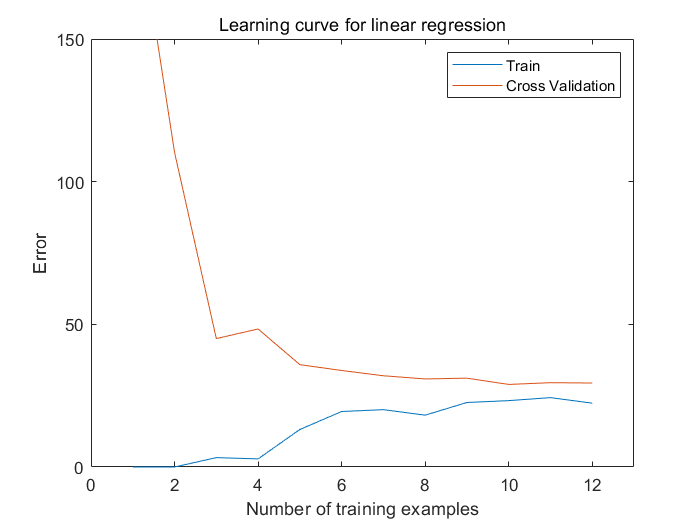


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  


% Train the model
lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411636e-01
Iteration    11 | Cost: 7.985027e-01
Iteration    12 | Cost: 7.561921e-01
Iteration    13 | Cost: 6.700969e-01
Iteration    14 | Cost: 4.869595e-01
Iteration    15 | Cost: 4.466487e-01
Iteration    16 | Cost: 4.425760e-01
Iteration    17 | Cost: 4.334760e-01
Iteration    18 | Cost: 4.275053e-01
Iteration    19 | Cost: 4.226692e-01
Iteration    20 | Cost: 4.140622e-01
Iteration    21 | Cost: 4.053245e-01
Iteration    22 | Cost: 3.984780e-01
Iteration    23 | Cost: 3.898224e-01
Iteration    24 | Cost: 3.874850e-01
Iteration    25 | Cost: 3.843754e-01
Iteration    26 | Cost: 3.829438e-01
Iteration    27 | Cost: 3.810190e-01
I

After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

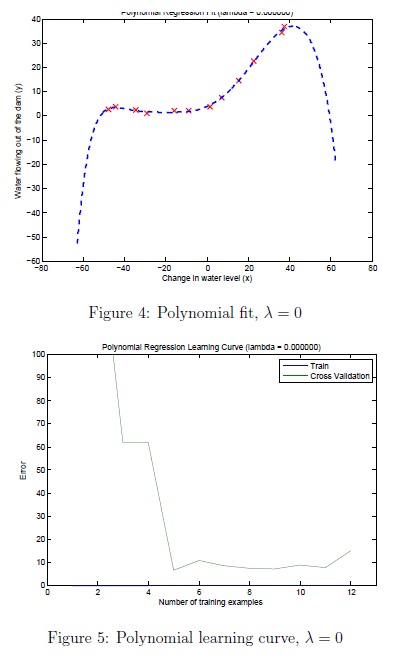

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

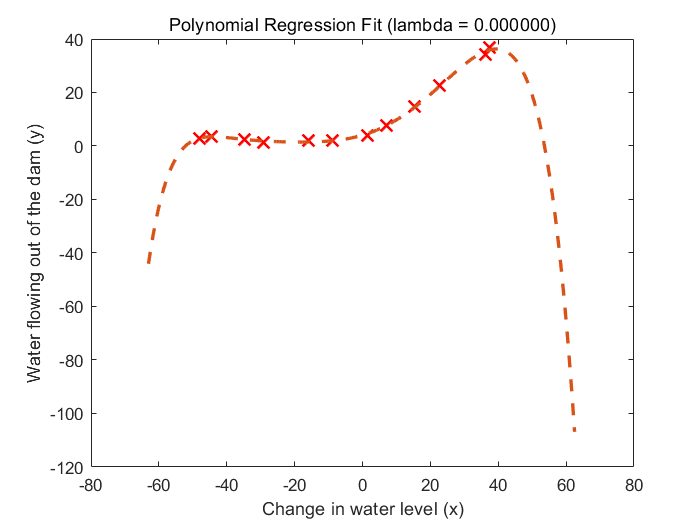

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 9.860761e-32
Iteration     4 | Cost: 0.000000e+00


theta =     0.6989
   -0.2531
   -0.5278
    0.1274
   -0.4936
    0.2143
   -0.4130
    0.2408
   -0.3554


Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 4.560072e-11
Iteration     5 | Cost: 4.560059e-11
Iteration     6 | Cost: 2.309960e-11
Iteration     7 | Cost: 1.551252e-14
Iteration     8 | Cost: 1.550239e-14
Iteration     9 | Cost: 7.917902e-15
Iteration    10 | Cost: 5.482829e-17
Iteration    11 | Cost: 3.321856e-17
Iteration    12 | Cost: 4.062935e-18
Iteration    13 | Cost: 3.711338e-18
Iteration    14 | Cost: 9.611423e-19
Iteration    15 | Cost: 5.369185e-29
Iteration    16 | Cost: 1.232595e-32
Iteration    17 | Cost: 0.000000e+00


theta =     0.5958
   -0.0733
   -0.6941
    0.2475
   -0.5432
    0.2515
   -0.4021
    0.2340
   -0.3222


Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration    11 | Cost: 7.703724e-08
Iteration    12 | Cost: 5.688321e-08
Iteration    13 | Cost: 5.385450e-09
Iteration    14 | Cost: 1.603656e-10
Iteration    15 | Cost: 1.516867e-11
Iteration    16 | Cost: 9.627464e-12
Iteration    17 | Cost: 2.794098e-12
Iteration    18 | Cost: 7.766256e-13
Iteration    19 | Cost: 1.571268e-13
Iteration    20 | Cost: 2.248292e-16
Iteration    21 | Cost: 5.079312e-17
Iteration    22 | Cost: 1.499570e-17
Iteration    23 | Cost: 3.850978e-18
Iteration    24 | Cost: 3.415932e-29
Iteration    25 | Cost: 3.040401e-31
Iteration    26 | Cost: 1.396941e-31
Iteration    27 | Cost: 7.395571e-32
I

theta =     6.3942
    6.0725
    6.1249
    5.6590
    2.6152
    5.0238
    0.2492
    4.2528
   -1.0254


Iteration     1 | Cost: 7.960488e-01
Iteration     2 | Cost: 2.114171e-01
Iteration     3 | Cost: 2.702642e-02
Iteration     4 | Cost: 3.974598e-19
Iteration     5 | Cost: 3.041491e-25
Iteration     6 | Cost: 1.130867e-25
Iteration     7 | Cost: 3.528137e-27
Iteration     8 | Cost: 6.473898e-28


theta =     6.5574
    7.5559
    6.9020
    5.1406
    1.9603
    3.8532
   -0.9940
    3.0128
   -2.2925


Iteration     1 | Cost: 9.143237e+01
Iteration     2 | Cost: 2.714529e+01
Iteration     3 | Cost: 2.522287e+00
Iteration     4 | Cost: 1.478489e+00
Iteration     5 | Cost: 8.205883e-01
Iteration     6 | Cost: 6.170430e-01
Iteration     7 | Cost: 1.944295e-01
Iteration     8 | Cost: 8.444134e-02
Iteration     9 | Cost: 7.065927e-02
Iteration    10 | Cost: 6.686511e-02
Iteration    11 | Cost: 6.229114e-02
Iteration    12 | Cost: 4.886051e-02
Iteration    13 | Cost: 4.666896e-02
Iteration    14 | Cost: 3.779361e-02
Iteration    15 | Cost: 3.365509e-02
Iteration    16 | Cost: 2.959754e-02
Iteration    17 | Cost: 2.865851e-02
Iteration    18 | Cost: 2.817567e-02
Iteration    19 | Cost: 2.808254e-02
Iteration    20 | Cost: 2.713577e-02
Iteration    21 | Cost: 2.664479e-02
Iteration    22 | Cost: 2.623820e-02
Iteration    23 | Cost: 2.484477e-02
Iteration    24 | Cost: 2.412881e-02
Iteration    25 | Cost: 2.410502e-02
Iteration    26 | Cost: 2.358888e-02
Iteration    27 | Cost: 2.319711e-02
I

theta =    10.4188
    8.3495
    5.5797
    5.1720
    2.6392
    2.0790
    1.0130
    0.1533
    0.4288


Iteration     1 | Cost: 6.685771e+01
Iteration     2 | Cost: 1.216701e+01
Iteration     3 | Cost: 1.795979e+00
Iteration     4 | Cost: 6.292963e-01
Iteration     5 | Cost: 2.225698e-01
Iteration     6 | Cost: 5.075312e-02
Iteration     7 | Cost: 4.971823e-02
Iteration     8 | Cost: 4.887221e-02
Iteration     9 | Cost: 4.848188e-02
Iteration    10 | Cost: 4.805640e-02
Iteration    11 | Cost: 4.761888e-02
Iteration    12 | Cost: 4.707479e-02
Iteration    13 | Cost: 4.655949e-02
Iteration    14 | Cost: 4.626432e-02
Iteration    15 | Cost: 4.623383e-02
Iteration    16 | Cost: 4.605953e-02
Iteration    17 | Cost: 4.580264e-02
Iteration    18 | Cost: 4.573037e-02
Iteration    19 | Cost: 4.549675e-02
Iteration    20 | Cost: 4.259384e-02
Iteration    21 | Cost: 4.111322e-02
Iteration    22 | Cost: 4.092478e-02
Iteration    23 | Cost: 3.831203e-02
Iteration    24 | Cost: 3.826055e-02
Iteration    25 | Cost: 3.784180e-02
Iteration    26 | Cost: 3.726198e-02
Iteration    27 | Cost: 3.721908e-02
I

theta =     9.3005
    5.0720
    9.0045
   10.9867
   -1.8846
    2.9140
    0.2901
   -3.8247
    2.5325


Iteration     1 | Cost: 7.107198e+01
Iteration     2 | Cost: 4.890266e+00
Iteration     3 | Cost: 2.478218e+00
Iteration     4 | Cost: 1.353835e+00
Iteration     5 | Cost: 1.178463e+00
Iteration     6 | Cost: 1.092424e+00
Iteration     7 | Cost: 7.418307e-01
Iteration     8 | Cost: 7.260364e-01
Iteration     9 | Cost: 7.061634e-01
Iteration    10 | Cost: 6.875105e-01
Iteration    11 | Cost: 6.638343e-01
Iteration    12 | Cost: 6.026448e-01
Iteration    13 | Cost: 5.481600e-01
Iteration    14 | Cost: 3.810755e-01
Iteration    15 | Cost: 3.374045e-01
Iteration    16 | Cost: 2.760027e-01
Iteration    17 | Cost: 2.711022e-01
Iteration    18 | Cost: 2.538201e-01
Iteration    19 | Cost: 2.005663e-01
Iteration    20 | Cost: 1.846591e-01
Iteration    21 | Cost: 1.652290e-01
Iteration    22 | Cost: 1.592726e-01
Iteration    23 | Cost: 1.428524e-01
Iteration    24 | Cost: 1.383586e-01
Iteration    25 | Cost: 1.184938e-01
Iteration    26 | Cost: 1.179348e-01
Iteration    27 | Cost: 1.159129e-01
I

theta =    10.8230
   12.8098
   11.6300
   -2.2558
  -10.8020
    3.6739
    1.2727
    3.4136
    8.6383


Iteration     1 | Cost: 6.233475e+01
Iteration     2 | Cost: 3.431422e+00
Iteration     3 | Cost: 2.307076e+00
Iteration     4 | Cost: 1.669557e+00
Iteration     5 | Cost: 1.320681e+00
Iteration     6 | Cost: 1.187742e+00
Iteration     7 | Cost: 9.986741e-01
Iteration     8 | Cost: 9.263827e-01
Iteration     9 | Cost: 9.261580e-01
Iteration    10 | Cost: 8.534259e-01
Iteration    11 | Cost: 8.258795e-01
Iteration    12 | Cost: 7.935804e-01
Iteration    13 | Cost: 6.042949e-01
Iteration    14 | Cost: 4.252250e-01
Iteration    15 | Cost: 3.278710e-01
Iteration    16 | Cost: 2.661974e-01
Iteration    17 | Cost: 2.232867e-01
Iteration    18 | Cost: 2.117489e-01
Iteration    19 | Cost: 1.871021e-01
Iteration    20 | Cost: 1.841797e-01
Iteration    21 | Cost: 1.733205e-01
Iteration    22 | Cost: 1.370138e-01
Iteration    23 | Cost: 1.260241e-01
Iteration    24 | Cost: 1.184639e-01
Iteration    25 | Cost: 1.049877e-01
Iteration    26 | Cost: 9.877999e-02
Iteration    27 | Cost: 9.576703e-02
I

theta =    11.2965
   13.3700
    8.4042
   -3.0073
   -4.4550
    0.0398
    4.4193
    6.6660
    2.0274


Iteration     1 | Cost: 5.922449e+01
Iteration     2 | Cost: 5.854872e+00
Iteration     3 | Cost: 5.301112e+00
Iteration     4 | Cost: 2.893773e+00
Iteration     5 | Cost: 1.989693e+00
Iteration     6 | Cost: 1.388242e+00
Iteration     7 | Cost: 1.310893e+00
Iteration     8 | Cost: 1.262622e+00
Iteration     9 | Cost: 1.156515e+00
Iteration    10 | Cost: 9.702586e-01
Iteration    11 | Cost: 8.742321e-01
Iteration    12 | Cost: 8.428406e-01
Iteration    13 | Cost: 6.258568e-01
Iteration    14 | Cost: 5.458390e-01
Iteration    15 | Cost: 4.932601e-01
Iteration    16 | Cost: 4.800753e-01
Iteration    17 | Cost: 4.440063e-01
Iteration    18 | Cost: 4.362691e-01
Iteration    19 | Cost: 4.031748e-01
Iteration    20 | Cost: 4.009199e-01
Iteration    21 | Cost: 3.852961e-01
Iteration    22 | Cost: 3.813433e-01
Iteration    23 | Cost: 3.704352e-01
Iteration    24 | Cost: 3.637613e-01
Iteration    25 | Cost: 3.528980e-01
Iteration    26 | Cost: 3.388113e-01
Iteration    27 | Cost: 3.321456e-01
I

theta =    11.0255
   11.8008
   16.3032
    7.0797
  -24.7689
  -20.1424
   19.5736
   20.0302
    1.5034


Iteration     1 | Cost: 5.599132e+01
Iteration     2 | Cost: 1.160850e+01
Iteration     3 | Cost: 5.777511e+00
Iteration     4 | Cost: 3.138721e+00
Iteration     5 | Cost: 1.743808e+00
Iteration     6 | Cost: 1.324477e+00
Iteration     7 | Cost: 1.115175e+00
Iteration     8 | Cost: 8.331651e-01
Iteration     9 | Cost: 7.154328e-01
Iteration    10 | Cost: 6.490466e-01
Iteration    11 | Cost: 6.420022e-01
Iteration    12 | Cost: 4.524692e-01
Iteration    13 | Cost: 3.381128e-01
Iteration    14 | Cost: 3.328403e-01
Iteration    15 | Cost: 3.264072e-01
Iteration    16 | Cost: 3.252194e-01
Iteration    17 | Cost: 3.242884e-01
Iteration    18 | Cost: 3.236544e-01
Iteration    19 | Cost: 3.221972e-01
Iteration    20 | Cost: 3.206125e-01
Iteration    21 | Cost: 3.197153e-01
Iteration    22 | Cost: 3.189897e-01
Iteration    23 | Cost: 3.165435e-01
Iteration    24 | Cost: 3.112981e-01
Iteration    25 | Cost: 3.081340e-01
Iteration    26 | Cost: 2.965050e-01
Iteration    27 | Cost: 2.925933e-01
I

theta =    11.1806
   10.3182
   20.4416
   17.7642
  -38.7604
  -36.6323
   39.0990
   25.6765
   -9.8001


Iteration     1 | Cost: 7.186879e+01
Iteration     2 | Cost: 2.278130e+01
Iteration     3 | Cost: 4.970159e+00
Iteration     4 | Cost: 1.355413e+00
Iteration     5 | Cost: 1.252814e+00
Iteration     6 | Cost: 1.187952e+00
Iteration     7 | Cost: 1.157390e+00
Iteration     8 | Cost: 1.037496e+00
Iteration     9 | Cost: 9.195845e-01
Iteration    10 | Cost: 8.848918e-01
Iteration    11 | Cost: 8.342791e-01
Iteration    12 | Cost: 7.925264e-01
Iteration    13 | Cost: 6.665888e-01
Iteration    14 | Cost: 5.321433e-01
Iteration    15 | Cost: 4.795174e-01
Iteration    16 | Cost: 4.170895e-01
Iteration    17 | Cost: 3.746013e-01
Iteration    18 | Cost: 3.528372e-01
Iteration    19 | Cost: 3.383320e-01
Iteration    20 | Cost: 3.373125e-01
Iteration    21 | Cost: 3.292630e-01
Iteration    22 | Cost: 3.214724e-01
Iteration    23 | Cost: 3.163275e-01
Iteration    24 | Cost: 3.161107e-01
Iteration    25 | Cost: 3.026133e-01
Iteration    26 | Cost: 2.706994e-01
Iteration    27 | Cost: 2.674261e-01
I

theta =    11.1194
   11.6495
   13.7667
    7.8314
  -12.8344
  -12.1278
   10.1714
    5.9243
   -4.0544


Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411636e-01
Iteration    11 | Cost: 7.985027e-01
Iteration    12 | Cost: 7.561921e-01
Iteration    13 | Cost: 6.700969e-01
Iteration    14 | Cost: 4.869595e-01
Iteration    15 | Cost: 4.466487e-01
Iteration    16 | Cost: 4.425760e-01
Iteration    17 | Cost: 4.334760e-01
Iteration    18 | Cost: 4.275053e-01
Iteration    19 | Cost: 4.226692e-01
Iteration    20 | Cost: 4.140622e-01
Iteration    21 | Cost: 4.053245e-01
Iteration    22 | Cost: 3.984780e-01
Iteration    23 | Cost: 3.898224e-01
Iteration    24 | Cost: 3.874850e-01
Iteration    25 | Cost: 3.843754e-01
Iteration    26 | Cost: 3.829438e-01
Iteration    27 | Cost: 3.810190e-01
I

theta =    11.2163
   11.2463
   14.0968
   10.9378
   -9.5698
  -12.5019
    4.6326
    0.7563
   -5.0244


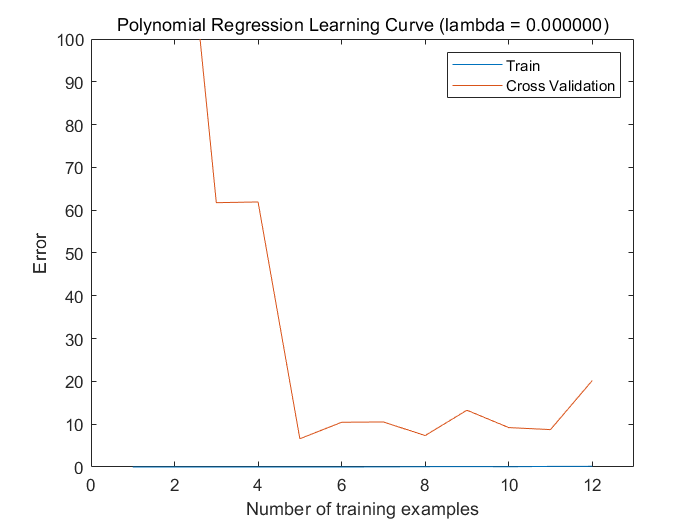

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.814702e+00
Iteration     5 | Cost: 7.711843e+00
Iteration     6 | Cost: 7.588232e+00
Iteration     7 | Cost: 7.481019e+00
Iteration     8 | Cost: 7.347791e+00
Iteration     9 | Cost: 7.337625e+00
Iteration    10 | Cost: 7.322456e+00
Iteration    11 | Cost: 7.315629e+00
Iteration    12 | Cost: 7.294255e+00
Iteration    13 | Cost: 7.285751e+00
Iteration    14 | Cost: 7.275672e+00
Iteration    15 | Cost: 7.275188e+00
Iteration    16 | Cost: 7.273599e+00
Iteration    17 | Cost: 7.272040e+00
Iteration    18 | Cost: 7.269890e+00
Iteration    19 | Cost: 7.269115e+00
Iteration    20 | Cost: 7.269027e+00
Iteration    21 | Cost: 7.268331e+00
Iteration    22 | Cost: 7.268261e+00
Iteration    23 | Cost: 7.268217e+00
Iteration    24 | Cost: 7.268211e+00
Iteration    25 | Cost: 7.268186e+00
Iteration    26 | Cost: 7.268160e+00
Iteration    27 | Cost: 7.268156e+00
I

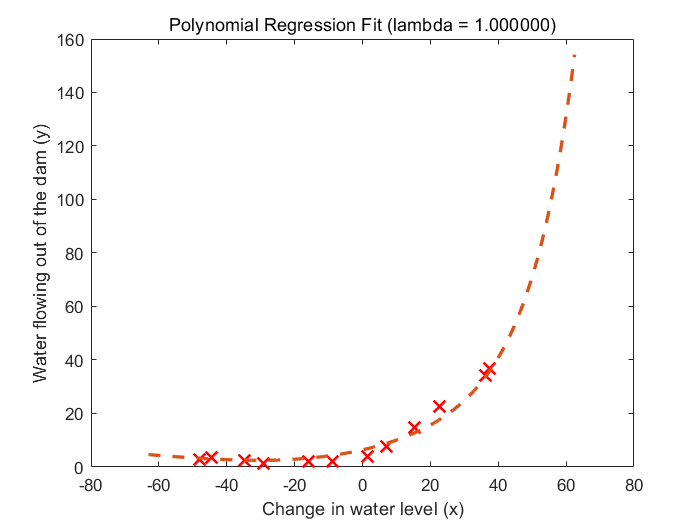


% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 7.403065e-27


theta =     2.1343
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


Iteration     1 | Cost: 2.032751e-01
Iteration     2 | Cost: 1.041953e-01
Iteration     3 | Cost: 7.367762e-02
Iteration     4 | Cost: 7.279642e-02
Iteration     5 | Cost: 7.269797e-02
Iteration     6 | Cost: 7.269533e-02
Iteration     7 | Cost: 7.269502e-02
Iteration     8 | Cost: 7.269437e-02
Iteration     9 | Cost: 7.269436e-02
Iteration    10 | Cost: 7.269436e-02
Iteration    11 | Cost: 7.269436e-02
Iteration    12 | Cost: 7.269436e-02
Iteration    13 | Cost: 7.269436e-02
Iteration    14 | Cost: 7.269436e-02
Iteration    15 | Cost: 7.269436e-02
Iteration    16 | Cost: 7.269436e-02
Iteration    17 | Cost: 7.269436e-02
Iteration    18 | Cost: 7.269436e-02
Iteration    19 | Cost: 7.269436e-02
Iteration    20 | Cost: 7.269436e-02


theta =     1.5366
    0.1334
   -0.2288
    0.1302
   -0.1147
    0.0645
   -0.0469
    0.0270
   -0.0180


Iteration     1 | Cost: 3.958682e+01
Iteration     2 | Cost: 2.172738e+01
Iteration     3 | Cost: 2.007128e+01
Iteration     4 | Cost: 1.908475e+01
Iteration     5 | Cost: 1.903782e+01
Iteration     6 | Cost: 1.872107e+01
Iteration     7 | Cost: 1.855211e+01
Iteration     8 | Cost: 1.852112e+01
Iteration     9 | Cost: 1.850029e+01
Iteration    10 | Cost: 1.849891e+01
Iteration    11 | Cost: 1.849887e+01
Iteration    12 | Cost: 1.849879e+01
Iteration    13 | Cost: 1.849879e+01
Iteration    14 | Cost: 1.849879e+01
Iteration    15 | Cost: 1.849879e+01
Iteration    16 | Cost: 1.849879e+01
Iteration    17 | Cost: 1.849879e+01
Iteration    18 | Cost: 1.849879e+01
Iteration    19 | Cost: 1.849879e+01
Iteration    20 | Cost: 1.849879e+01
Iteration    21 | Cost: 1.849879e+01
Iteration    22 | Cost: 1.849879e+01
Iteration    24 | Cost: 1.849879e+01


theta =    10.4295
    6.5586
    3.4554
    4.2571
    2.6837
    2.5951
    1.7423
    1.5311
    1.0632


Iteration     1 | Cost: 1.883439e+01
Iteration     2 | Cost: 1.695119e+01
Iteration     3 | Cost: 1.546680e+01
Iteration     4 | Cost: 1.486258e+01
Iteration     5 | Cost: 1.462699e+01
Iteration     6 | Cost: 1.460173e+01
Iteration     7 | Cost: 1.458789e+01
Iteration     8 | Cost: 1.458160e+01
Iteration     9 | Cost: 1.457865e+01
Iteration    10 | Cost: 1.457606e+01
Iteration    11 | Cost: 1.457596e+01
Iteration    12 | Cost: 1.457591e+01
Iteration    13 | Cost: 1.457590e+01
Iteration    14 | Cost: 1.457588e+01
Iteration    15 | Cost: 1.457587e+01
Iteration    16 | Cost: 1.457586e+01
Iteration    17 | Cost: 1.457586e+01
Iteration    18 | Cost: 1.457586e+01
Iteration    19 | Cost: 1.457586e+01
Iteration    20 | Cost: 1.457586e+01
Iteration    21 | Cost: 1.457586e+01
Iteration    22 | Cost: 1.457586e+01
Iteration    23 | Cost: 1.457586e+01
Iteration    24 | Cost: 1.457586e+01
Iteration    25 | Cost: 1.457586e+01
Iteration    26 | Cost: 1.457586e+01
Iteration    27 | Cost: 1.457586e+01
I

theta =    10.8907
    6.7348
    3.6769
    4.5100
    2.9536
    2.8468
    1.9864
    1.7437
    1.2568


Iteration     1 | Cost: 9.507932e+01
Iteration     2 | Cost: 3.745281e+01
Iteration     3 | Cost: 1.603853e+01
Iteration     4 | Cost: 1.259101e+01
Iteration     5 | Cost: 1.224802e+01
Iteration     6 | Cost: 1.203684e+01
Iteration     7 | Cost: 1.176788e+01
Iteration     8 | Cost: 1.170462e+01
Iteration     9 | Cost: 1.167517e+01
Iteration    10 | Cost: 1.166577e+01
Iteration    11 | Cost: 1.166401e+01
Iteration    12 | Cost: 1.166155e+01
Iteration    13 | Cost: 1.166145e+01
Iteration    14 | Cost: 1.166140e+01
Iteration    15 | Cost: 1.166110e+01
Iteration    16 | Cost: 1.166080e+01
Iteration    17 | Cost: 1.166076e+01
Iteration    18 | Cost: 1.166073e+01
Iteration    19 | Cost: 1.166072e+01
Iteration    20 | Cost: 1.166072e+01
Iteration    21 | Cost: 1.166072e+01
Iteration    22 | Cost: 1.166072e+01
Iteration    23 | Cost: 1.166072e+01
Iteration    24 | Cost: 1.166072e+01
Iteration    25 | Cost: 1.166072e+01
Iteration    26 | Cost: 1.166072e+01
Iteration    27 | Cost: 1.166072e+01
I

Iteration    35 | Cost: 1.166072e+01
Iteration    36 | Cost: 1.166072e+01
Iteration    37 | Cost: 1.166072e+01
Iteration    38 | Cost: 1.166072e+01
Iteration    39 | Cost: 1.166072e+01
Iteration    40 | Cost: 1.166072e+01
Iteration    41 | Cost: 1.166072e+01
Iteration    42 | Cost: 1.166072e+01
Iteration    43 | Cost: 1.166072e+01
Iteration    44 | Cost: 1.166072e+01
Iteration    45 | Cost: 1.166072e+01
Iteration    46 | Cost: 1.166072e+01
Iteration    47 | Cost: 1.166072e+01
Iteration    48 | Cost: 1.166072e+01
Iteration    49 | Cost: 1.166072e+01
Iteration    50 | Cost: 1.166072e+01
Iteration    51 | Cost: 1.166072e+01


theta =    10.8770
    6.7354
    3.6750
    4.5132
    2.9487
    2.8522
    1.9799
    1.7503
    1.2496


Iteration     1 | Cost: 7.115385e+01
Iteration     2 | Cost: 2.111452e+01
Iteration     3 | Cost: 1.314175e+01
Iteration     4 | Cost: 1.054644e+01
Iteration     5 | Cost: 1.036773e+01
Iteration     6 | Cost: 1.034120e+01
Iteration     7 | Cost: 1.026977e+01
Iteration     8 | Cost: 1.022714e+01
Iteration     9 | Cost: 1.019759e+01
Iteration    10 | Cost: 1.015385e+01
Iteration    11 | Cost: 1.014049e+01
Iteration    12 | Cost: 1.013163e+01
Iteration    13 | Cost: 1.013124e+01
Iteration    14 | Cost: 1.012855e+01
Iteration    15 | Cost: 1.012593e+01
Iteration    16 | Cost: 1.011958e+01
Iteration    17 | Cost: 1.011929e+01
Iteration    18 | Cost: 1.011892e+01
Iteration    19 | Cost: 1.011888e+01
Iteration    20 | Cost: 1.011885e+01
Iteration    21 | Cost: 1.011883e+01
Iteration    22 | Cost: 1.011882e+01
Iteration    23 | Cost: 1.011882e+01
Iteration    24 | Cost: 1.011882e+01
Iteration    25 | Cost: 1.011882e+01
Iteration    26 | Cost: 1.011882e+01
Iteration    27 | Cost: 1.011882e+01
I

theta =    10.1905
    6.5116
    4.4218
    4.5250
    3.1365
    3.0210
    1.9522
    1.9624
    1.1301


Iteration     1 | Cost: 7.518060e+01
Iteration     2 | Cost: 1.380985e+01
Iteration     3 | Cost: 1.067080e+01
Iteration     4 | Cost: 9.983701e+00
Iteration     5 | Cost: 9.679877e+00
Iteration     6 | Cost: 9.627617e+00
Iteration     7 | Cost: 9.551271e+00
Iteration     8 | Cost: 9.521678e+00
Iteration     9 | Cost: 9.504739e+00
Iteration    10 | Cost: 9.445054e+00
Iteration    11 | Cost: 9.430966e+00
Iteration    12 | Cost: 9.422694e+00
Iteration    13 | Cost: 9.420839e+00
Iteration    14 | Cost: 9.419565e+00
Iteration    15 | Cost: 9.419107e+00
Iteration    16 | Cost: 9.417864e+00
Iteration    17 | Cost: 9.417298e+00
Iteration    18 | Cost: 9.416722e+00
Iteration    19 | Cost: 9.416642e+00
Iteration    20 | Cost: 9.416361e+00
Iteration    21 | Cost: 9.416355e+00
Iteration    22 | Cost: 9.416347e+00
Iteration    23 | Cost: 9.416339e+00
Iteration    24 | Cost: 9.416325e+00
Iteration    25 | Cost: 9.416320e+00
Iteration    26 | Cost: 9.416319e+00
Iteration    27 | Cost: 9.416318e+00
I

theta =    10.9237
    7.6554
    3.8984
    4.0432
    2.7162
    2.4767
    1.7531
    1.5295
    1.0868


Iteration     1 | Cost: 6.611004e+01
Iteration     2 | Cost: 1.315555e+01
Iteration     3 | Cost: 1.256600e+01
Iteration     4 | Cost: 9.982682e+00
Iteration     5 | Cost: 9.091355e+00
Iteration     6 | Cost: 8.599350e+00
Iteration     7 | Cost: 8.383903e+00
Iteration     8 | Cost: 8.287118e+00
Iteration     9 | Cost: 8.283081e+00
Iteration    10 | Cost: 8.257551e+00
Iteration    11 | Cost: 8.256256e+00
Iteration    12 | Cost: 8.256242e+00
Iteration    13 | Cost: 8.256233e+00
Iteration    14 | Cost: 8.256225e+00
Iteration    15 | Cost: 8.256224e+00
Iteration    16 | Cost: 8.256224e+00
Iteration    17 | Cost: 8.256224e+00
Iteration    18 | Cost: 8.256224e+00
Iteration    19 | Cost: 8.256224e+00
Iteration    20 | Cost: 8.256224e+00
Iteration    21 | Cost: 8.256224e+00
Iteration    22 | Cost: 8.256224e+00
Iteration    23 | Cost: 8.256224e+00
Iteration    24 | Cost: 8.256224e+00
Iteration    25 | Cost: 8.256224e+00
Iteration    26 | Cost: 8.256224e+00
Iteration    27 | Cost: 8.256224e+00
I

theta =    10.9980
    7.5756
    4.0258
    3.9578
    2.7508
    2.4717
    1.7000
    1.5989
    0.9739


Iteration     1 | Cost: 6.224886e+01
Iteration     2 | Cost: 1.103234e+01
Iteration     3 | Cost: 1.031664e+01
Iteration     4 | Cost: 8.190841e+00
Iteration     5 | Cost: 8.026839e+00
Iteration     6 | Cost: 8.002404e+00
Iteration     7 | Cost: 7.966026e+00
Iteration     8 | Cost: 7.930815e+00
Iteration     9 | Cost: 7.901985e+00
Iteration    10 | Cost: 7.866498e+00
Iteration    11 | Cost: 7.850828e+00
Iteration    12 | Cost: 7.844060e+00
Iteration    13 | Cost: 7.815734e+00
Iteration    14 | Cost: 7.814552e+00
Iteration    15 | Cost: 7.811933e+00
Iteration    16 | Cost: 7.810976e+00
Iteration    17 | Cost: 7.808241e+00
Iteration    18 | Cost: 7.805376e+00
Iteration    19 | Cost: 7.802391e+00
Iteration    20 | Cost: 7.802137e+00
Iteration    21 | Cost: 7.802084e+00
Iteration    22 | Cost: 7.802080e+00
Iteration    23 | Cost: 7.802080e+00
Iteration    24 | Cost: 7.802079e+00
Iteration    25 | Cost: 7.802078e+00
Iteration    26 | Cost: 7.802078e+00
Iteration    27 | Cost: 7.802077e+00
I

theta =    10.5912
    7.3473
    4.6339
    4.0385
    2.7751
    2.5740
    1.6379
    1.7033
    0.8915


Iteration     1 | Cost: 5.861091e+01
Iteration     2 | Cost: 1.029928e+01
Iteration     3 | Cost: 1.000150e+01
Iteration     4 | Cost: 8.267232e+00
Iteration     5 | Cost: 7.746579e+00
Iteration     6 | Cost: 7.274815e+00
Iteration     7 | Cost: 7.194562e+00
Iteration     8 | Cost: 7.152573e+00
Iteration     9 | Cost: 7.097993e+00
Iteration    10 | Cost: 7.093618e+00
Iteration    11 | Cost: 7.087873e+00
Iteration    12 | Cost: 7.072737e+00
Iteration    13 | Cost: 7.066538e+00
Iteration    14 | Cost: 7.065896e+00
Iteration    15 | Cost: 7.064981e+00
Iteration    16 | Cost: 7.064923e+00
Iteration    17 | Cost: 7.064706e+00
Iteration    18 | Cost: 7.064636e+00
Iteration    19 | Cost: 7.064535e+00
Iteration    20 | Cost: 7.064521e+00
Iteration    21 | Cost: 7.064482e+00
Iteration    22 | Cost: 7.064471e+00
Iteration    23 | Cost: 7.064424e+00
Iteration    24 | Cost: 7.064421e+00
Iteration    25 | Cost: 7.064417e+00
Iteration    26 | Cost: 7.064414e+00
Iteration    27 | Cost: 7.064405e+00
I

theta =    10.6842
    7.3447
    4.7111
    3.9310
    2.8775
    2.4998
    1.6461
    1.7476
    0.7563


Iteration     1 | Cost: 7.248552e+01
Iteration     2 | Cost: 2.583449e+01
Iteration     3 | Cost: 8.711534e+00
Iteration     4 | Cost: 6.790164e+00
Iteration     5 | Cost: 6.687293e+00
Iteration     6 | Cost: 6.663962e+00
Iteration     7 | Cost: 6.595243e+00
Iteration     8 | Cost: 6.538932e+00
Iteration     9 | Cost: 6.513460e+00
Iteration    10 | Cost: 6.477429e+00
Iteration    11 | Cost: 6.451620e+00
Iteration    12 | Cost: 6.449203e+00
Iteration    13 | Cost: 6.428503e+00
Iteration    14 | Cost: 6.426517e+00
Iteration    15 | Cost: 6.424335e+00
Iteration    16 | Cost: 6.424266e+00
Iteration    17 | Cost: 6.424039e+00
Iteration    18 | Cost: 6.423949e+00
Iteration    19 | Cost: 6.423880e+00
Iteration    20 | Cost: 6.423857e+00
Iteration    21 | Cost: 6.423835e+00
Iteration    22 | Cost: 6.423806e+00
Iteration    23 | Cost: 6.423802e+00
Iteration    24 | Cost: 6.423797e+00
Iteration    25 | Cost: 6.423792e+00
Iteration    26 | Cost: 6.423788e+00
Iteration    27 | Cost: 6.423785e+00
I

theta =    10.6627
    7.3215
    4.7348
    3.9438
    2.8820
    2.5101
    1.6466
    1.7546
    0.7562


Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.814702e+00
Iteration     5 | Cost: 7.711843e+00
Iteration     6 | Cost: 7.588232e+00
Iteration     7 | Cost: 7.481019e+00
Iteration     8 | Cost: 7.347791e+00
Iteration     9 | Cost: 7.337625e+00
Iteration    10 | Cost: 7.322456e+00
Iteration    11 | Cost: 7.315629e+00
Iteration    12 | Cost: 7.294255e+00
Iteration    13 | Cost: 7.285751e+00
Iteration    14 | Cost: 7.275672e+00
Iteration    15 | Cost: 7.275188e+00
Iteration    16 | Cost: 7.273599e+00
Iteration    17 | Cost: 7.272040e+00
Iteration    18 | Cost: 7.269890e+00
Iteration    19 | Cost: 7.269115e+00
Iteration    20 | Cost: 7.269027e+00
Iteration    21 | Cost: 7.268331e+00
Iteration    22 | Cost: 7.268261e+00
Iteration    23 | Cost: 7.268217e+00
Iteration    24 | Cost: 7.268211e+00
Iteration    25 | Cost: 7.268186e+00
Iteration    26 | Cost: 7.268160e+00
Iteration    27 | Cost: 7.268156e+00
I

theta =    11.2176
    8.5852
    5.2127
    3.5911
    2.2830
    1.7603
    1.0681
    1.1076
    0.3940


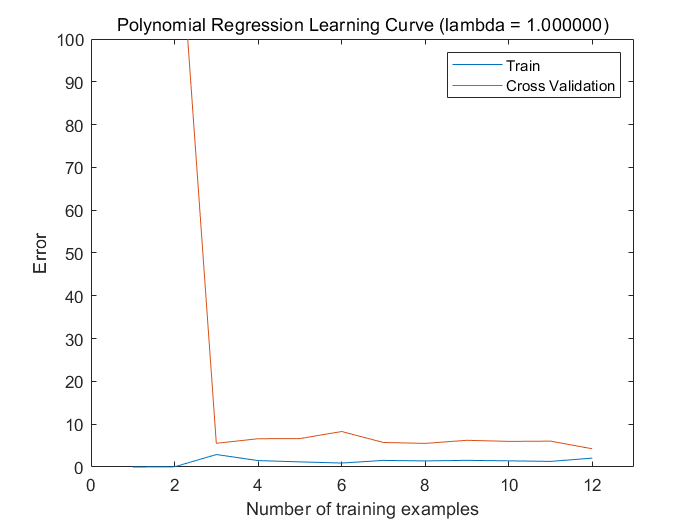

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

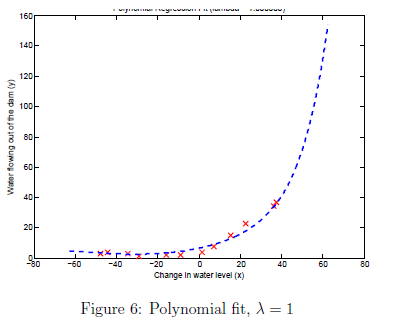

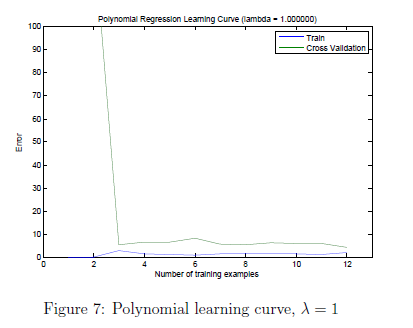

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

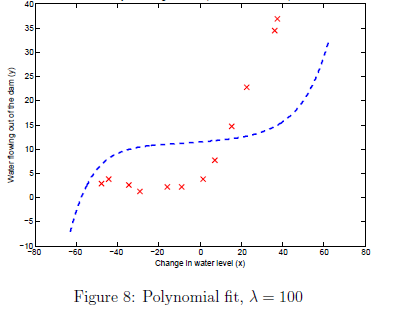

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

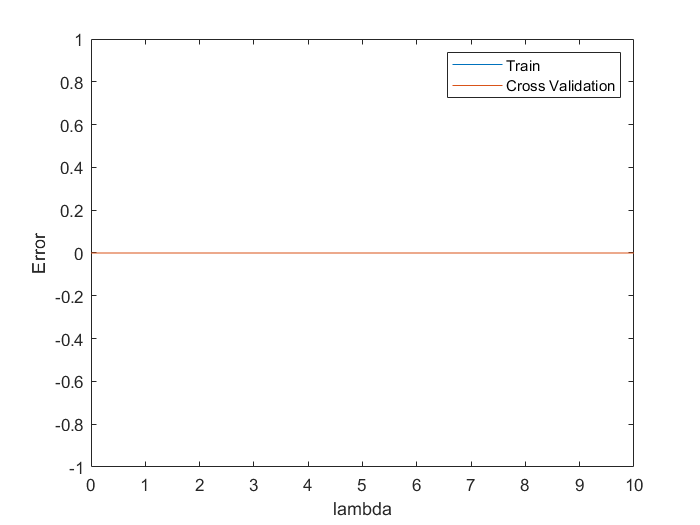

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.000000	0.000000
0.001000	0.000000	0.000000
0.003000	0.000000	0.000000
0.010000	0.000000	0.000000
0.030000	0.000000	0.000000
0.100000	0.000000	0.000000
0.300000	0.000000	0.000000
1.000000	0.000000	0.000000
3.000000	0.000000	0.000000
10.000000	0.000000	0.000000


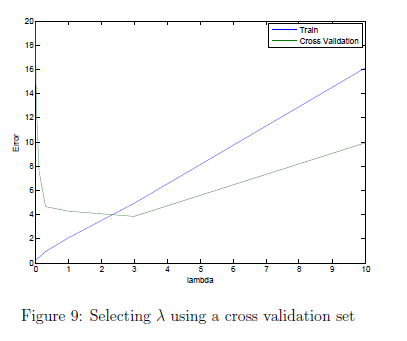

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565794e-09
Iteration    13 | Cost: 1.565336e-09
Iteration    14 | Cost: 1.550962e-09
Iteration    15 | Cost: 1.184142e-09
Iteration    16 | Cost: 3.067194e-11
Iteration    17 | Cost: 2.688543e-11
Iteration    18 | Cost: 1.776237e-11
Iteration    19 | Cost: 4.202177e-12
Iteration    20 | Cost: 4.110343e-12
Iteration    21 | Cost: 3.781115e-12
Iteration    22 | Cost: 2.651665e-12
Iteration    23 | Cost: 3.558945e-13
Iteration    24 | Cost: 8.517653e-14
Iteration    25 | Cost: 3.498353e-22
Iteration    26 | Cost: 1.175038e-24
Iteration    27 | Cost: 2.746775e-25
I

theta =     2.1343
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000


Iteration     1 | Cost: 5.523568e-02
Iteration     2 | Cost: 3.367312e-03
Iteration     3 | Cost: 3.037042e-03
Iteration     4 | Cost: 3.002440e-03
Iteration     5 | Cost: 2.989285e-03
Iteration     6 | Cost: 2.746466e-03
Iteration     7 | Cost: 2.209816e-03
Iteration     8 | Cost: 1.947360e-03
Iteration     9 | Cost: 1.935227e-03
Iteration    10 | Cost: 1.933886e-03
Iteration    11 | Cost: 1.933744e-03
Iteration    12 | Cost: 1.933710e-03
Iteration    13 | Cost: 1.931323e-03
Iteration    14 | Cost: 1.931002e-03
Iteration    15 | Cost: 1.930035e-03
Iteration    16 | Cost: 1.930032e-03
Iteration    17 | Cost: 1.930028e-03
Iteration    18 | Cost: 1.930028e-03
Iteration    19 | Cost: 1.930027e-03
Iteration    20 | Cost: 1.930027e-03
Iteration    21 | Cost: 1.930027e-03
Iteration    22 | Cost: 1.930027e-03
Iteration    23 | Cost: 1.930026e-03
Iteration    24 | Cost: 1.930025e-03
Iteration    25 | Cost: 1.930025e-03
Iteration    26 | Cost: 1.930022e-03
Iteration    27 | Cost: 1.930016e-03
I

theta =     1.3427
    0.3543
   -0.6076
    0.3455
   -0.3046
    0.1713
   -0.1246
    0.0716
   -0.0479


Iteration     1 | Cost: 3.032734e+01
Iteration     2 | Cost: 1.226927e+00
Iteration     3 | Cost: 7.383164e-01
Iteration     4 | Cost: 2.727993e-01
Iteration     5 | Cost: 2.622976e-01
Iteration     6 | Cost: 2.616915e-01
Iteration     7 | Cost: 2.612460e-01
Iteration     8 | Cost: 2.600987e-01
Iteration     9 | Cost: 2.597820e-01
Iteration    10 | Cost: 2.293193e-01
Iteration    11 | Cost: 2.245222e-01
Iteration    12 | Cost: 2.233166e-01
Iteration    13 | Cost: 2.216354e-01
Iteration    14 | Cost: 2.211828e-01
Iteration    15 | Cost: 2.208628e-01
Iteration    16 | Cost: 2.207706e-01
Iteration    17 | Cost: 2.207157e-01
Iteration    18 | Cost: 2.206993e-01
Iteration    19 | Cost: 2.206900e-01
Iteration    20 | Cost: 2.206839e-01
Iteration    21 | Cost: 2.206780e-01
Iteration    22 | Cost: 2.206654e-01
Iteration    23 | Cost: 2.206532e-01
Iteration    24 | Cost: 2.206318e-01
Iteration    25 | Cost: 2.206177e-01
Iteration    26 | Cost: 2.206127e-01
Iteration    27 | Cost: 2.205936e-01
I

theta =    10.3722
    7.5519
    4.6101
    4.8100
    3.4476
    2.9634
    2.1801
    1.7719
    1.3079


Iteration     1 | Cost: 9.871955e-01
Iteration     2 | Cost: 3.772825e-01
Iteration     3 | Cost: 2.193567e-01
Iteration     4 | Cost: 1.925157e-01
Iteration     5 | Cost: 1.805322e-01
Iteration     6 | Cost: 1.737281e-01
Iteration     7 | Cost: 1.698174e-01
Iteration     8 | Cost: 1.698004e-01
Iteration     9 | Cost: 1.697519e-01
Iteration    10 | Cost: 1.696858e-01
Iteration    11 | Cost: 1.696782e-01
Iteration    12 | Cost: 1.696679e-01
Iteration    13 | Cost: 1.696382e-01
Iteration    14 | Cost: 1.695444e-01
Iteration    15 | Cost: 1.694965e-01
Iteration    16 | Cost: 1.694920e-01
Iteration    17 | Cost: 1.694068e-01
Iteration    18 | Cost: 1.693531e-01
Iteration    19 | Cost: 1.692667e-01
Iteration    20 | Cost: 1.691559e-01
Iteration    21 | Cost: 1.691325e-01
Iteration    22 | Cost: 1.691260e-01
Iteration    23 | Cost: 1.691233e-01
Iteration    24 | Cost: 1.691224e-01
Iteration    25 | Cost: 1.691220e-01
Iteration    26 | Cost: 1.691205e-01
Iteration    27 | Cost: 1.691148e-01
I

theta =    10.4686
    8.2460
    4.9300
    4.5512
    3.1371
    2.3884
    1.6155
    1.1610
    0.7408


Iteration     1 | Cost: 9.146884e+01
Iteration     2 | Cost: 2.886188e+01
Iteration     3 | Cost: 6.592840e+00
Iteration     4 | Cost: 1.795212e+00
Iteration     5 | Cost: 8.530978e-01
Iteration     6 | Cost: 4.928841e-01
Iteration     7 | Cost: 2.582513e-01
Iteration     8 | Cost: 2.580628e-01
Iteration     9 | Cost: 2.368277e-01
Iteration    10 | Cost: 2.164349e-01
Iteration    11 | Cost: 2.074842e-01
Iteration    12 | Cost: 1.972053e-01
Iteration    13 | Cost: 1.959126e-01
Iteration    14 | Cost: 1.858238e-01
Iteration    15 | Cost: 1.811496e-01
Iteration    16 | Cost: 1.708102e-01
Iteration    17 | Cost: 1.600387e-01
Iteration    18 | Cost: 1.593929e-01
Iteration    19 | Cost: 1.590234e-01
Iteration    20 | Cost: 1.586384e-01
Iteration    21 | Cost: 1.582801e-01
Iteration    22 | Cost: 1.536280e-01
Iteration    23 | Cost: 1.487890e-01
Iteration    24 | Cost: 1.475792e-01
Iteration    25 | Cost: 1.460869e-01
Iteration    26 | Cost: 1.447812e-01
Iteration    27 | Cost: 1.444729e-01
I

theta =    10.4031
    8.2277
    4.9554
    4.5626
    3.1210
    2.4185
    1.5796
    1.1989
    0.6979


Iteration     1 | Cost: 6.690068e+01
Iteration     2 | Cost: 1.226122e+01
Iteration     3 | Cost: 1.918807e+00
Iteration     4 | Cost: 7.408589e-01
Iteration     5 | Cost: 3.343811e-01
Iteration     6 | Cost: 1.632769e-01
Iteration     7 | Cost: 1.622905e-01
Iteration     8 | Cost: 1.614093e-01
Iteration     9 | Cost: 1.607864e-01
Iteration    10 | Cost: 1.603900e-01
Iteration    11 | Cost: 1.595767e-01
Iteration    12 | Cost: 1.584796e-01
Iteration    13 | Cost: 1.578666e-01
Iteration    14 | Cost: 1.577368e-01
Iteration    15 | Cost: 1.574622e-01
Iteration    16 | Cost: 1.572499e-01
Iteration    17 | Cost: 1.568692e-01
Iteration    18 | Cost: 1.565147e-01
Iteration    19 | Cost: 1.562808e-01
Iteration    20 | Cost: 1.561317e-01
Iteration    21 | Cost: 1.559260e-01
Iteration    22 | Cost: 1.557263e-01
Iteration    23 | Cost: 1.552124e-01
Iteration    24 | Cost: 1.545744e-01
Iteration    25 | Cost: 1.531122e-01
Iteration    26 | Cost: 1.516294e-01
Iteration    27 | Cost: 1.507618e-01
I

theta =     9.8155
    6.8977
    6.2694
    6.1651
    2.0663
    2.9136
    1.4431
    0.4585
    1.2595


Iteration     1 | Cost: 7.111306e+01
Iteration     2 | Cost: 4.803470e+00
Iteration     3 | Cost: 2.620374e+00
Iteration     4 | Cost: 1.535053e+00
Iteration     5 | Cost: 1.291423e+00
Iteration     6 | Cost: 7.629676e-01
Iteration     7 | Cost: 2.958943e-01
Iteration     8 | Cost: 2.538842e-01
Iteration     9 | Cost: 2.536628e-01
Iteration    10 | Cost: 2.509580e-01
Iteration    11 | Cost: 2.491922e-01
Iteration    12 | Cost: 2.488931e-01
Iteration    13 | Cost: 2.470797e-01
Iteration    14 | Cost: 2.465594e-01
Iteration    15 | Cost: 2.443735e-01
Iteration    16 | Cost: 2.442921e-01
Iteration    17 | Cost: 2.440353e-01
Iteration    18 | Cost: 2.438726e-01
Iteration    19 | Cost: 2.433453e-01
Iteration    20 | Cost: 2.433308e-01
Iteration    21 | Cost: 2.432724e-01
Iteration    22 | Cost: 2.432343e-01
Iteration    23 | Cost: 2.431725e-01
Iteration    24 | Cost: 2.430699e-01
Iteration    25 | Cost: 2.429193e-01
Iteration    26 | Cost: 2.428736e-01
Iteration    27 | Cost: 2.427020e-01
I

theta =    11.1676
   12.3713
    7.5143
    0.1916
   -0.6651
    1.1415
    0.3021
    1.4559
    1.1608


Iteration     1 | Cost: 6.237381e+01
Iteration     2 | Cost: 6.360621e+00
Iteration     3 | Cost: 3.476497e+00
Iteration     4 | Cost: 1.933373e+00
Iteration     5 | Cost: 1.568866e+00
Iteration     6 | Cost: 1.384420e+00
Iteration     7 | Cost: 1.306733e+00
Iteration     8 | Cost: 1.213884e+00
Iteration     9 | Cost: 1.111654e+00
Iteration    10 | Cost: 1.007563e+00
Iteration    11 | Cost: 7.978854e-01
Iteration    12 | Cost: 7.475915e-01
Iteration    13 | Cost: 6.017005e-01
Iteration    14 | Cost: 5.268245e-01
Iteration    15 | Cost: 2.947582e-01
Iteration    16 | Cost: 2.281618e-01
Iteration    17 | Cost: 2.258628e-01
Iteration    18 | Cost: 2.252555e-01
Iteration    19 | Cost: 2.252258e-01
Iteration    20 | Cost: 2.251299e-01
Iteration    21 | Cost: 2.241623e-01
Iteration    22 | Cost: 2.236507e-01
Iteration    23 | Cost: 2.231662e-01
Iteration    24 | Cost: 2.230727e-01
Iteration    25 | Cost: 2.230106e-01
Iteration    26 | Cost: 2.230058e-01
Iteration    27 | Cost: 2.229572e-01
I

theta =    11.3443
   12.5781
    6.9740
   -0.4112
    0.9456
    0.4727
    0.6563
    2.2554
   -0.3810


Iteration     1 | Cost: 5.925570e+01
Iteration     2 | Cost: 6.510520e+00
Iteration     3 | Cost: 5.854467e+00
Iteration     4 | Cost: 3.048818e+00
Iteration     5 | Cost: 2.114770e+00
Iteration     6 | Cost: 1.585617e+00
Iteration     7 | Cost: 1.476417e+00
Iteration     8 | Cost: 1.386047e+00
Iteration     9 | Cost: 1.257316e+00
Iteration    10 | Cost: 1.143240e+00
Iteration    11 | Cost: 9.044389e-01
Iteration    12 | Cost: 8.107628e-01
Iteration    13 | Cost: 7.150223e-01
Iteration    14 | Cost: 5.978512e-01
Iteration    15 | Cost: 5.711283e-01
Iteration    16 | Cost: 5.386792e-01
Iteration    17 | Cost: 5.239454e-01
Iteration    18 | Cost: 5.138746e-01
Iteration    19 | Cost: 5.102969e-01
Iteration    20 | Cost: 4.877679e-01
Iteration    21 | Cost: 4.813065e-01
Iteration    22 | Cost: 4.595438e-01
Iteration    23 | Cost: 4.585893e-01
Iteration    24 | Cost: 4.574192e-01
Iteration    25 | Cost: 4.572667e-01
Iteration    26 | Cost: 4.556148e-01
Iteration    27 | Cost: 4.535573e-01
I

theta =    10.9753
   11.8308
   10.9050
    2.6469
   -4.1495
   -1.0056
   -0.1761
    0.1308
    0.7381


Iteration     1 | Cost: 5.601835e+01
Iteration     2 | Cost: 2.100417e+00
Iteration     3 | Cost: 1.628627e+00
Iteration     4 | Cost: 1.508200e+00
Iteration     5 | Cost: 1.376450e+00
Iteration     6 | Cost: 1.302141e+00
Iteration     7 | Cost: 1.259795e+00
Iteration     8 | Cost: 9.561929e-01
Iteration     9 | Cost: 7.687173e-01
Iteration    10 | Cost: 7.124677e-01
Iteration    11 | Cost: 5.502543e-01
Iteration    12 | Cost: 4.547349e-01
Iteration    13 | Cost: 4.446989e-01
Iteration    14 | Cost: 4.388018e-01
Iteration    15 | Cost: 4.380910e-01
Iteration    16 | Cost: 4.376868e-01
Iteration    17 | Cost: 4.287695e-01
Iteration    18 | Cost: 4.159044e-01
Iteration    19 | Cost: 4.106151e-01
Iteration    20 | Cost: 4.103533e-01
Iteration    21 | Cost: 4.032306e-01
Iteration    22 | Cost: 3.998049e-01
Iteration    23 | Cost: 3.981611e-01
Iteration    24 | Cost: 3.960916e-01
Iteration    25 | Cost: 3.960640e-01
Iteration    26 | Cost: 3.959519e-01
Iteration    27 | Cost: 3.954354e-01
I

theta =    11.0620
   11.9020
   10.2427
    2.9755
   -2.8735
   -2.1777
    0.9325
    0.5388
   -1.2685


Iteration     1 | Cost: 7.187496e+01
Iteration     2 | Cost: 2.281183e+01
Iteration     3 | Cost: 5.007884e+00
Iteration     4 | Cost: 1.413732e+00
Iteration     5 | Cost: 1.311430e+00
Iteration     6 | Cost: 1.246469e+00
Iteration     7 | Cost: 1.216876e+00
Iteration     8 | Cost: 1.098700e+00
Iteration     9 | Cost: 9.722434e-01
Iteration    10 | Cost: 9.573930e-01
Iteration    11 | Cost: 8.953441e-01
Iteration    12 | Cost: 8.725177e-01
Iteration    13 | Cost: 7.920433e-01
Iteration    14 | Cost: 7.674733e-01
Iteration    15 | Cost: 6.662254e-01
Iteration    16 | Cost: 6.376585e-01
Iteration    17 | Cost: 5.663612e-01
Iteration    18 | Cost: 4.618086e-01
Iteration    19 | Cost: 4.558422e-01
Iteration    20 | Cost: 4.452356e-01
Iteration    21 | Cost: 4.383700e-01
Iteration    22 | Cost: 4.355500e-01
Iteration    23 | Cost: 4.314686e-01
Iteration    24 | Cost: 4.286527e-01
Iteration    25 | Cost: 4.279870e-01
Iteration    26 | Cost: 4.271590e-01
Iteration    27 | Cost: 4.227110e-01
I

theta =    11.0274
   11.7350
   10.4252
    3.4451
   -3.0085
   -2.4369
    0.9037
    0.3447
   -1.3877


Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.964510e+00
Iteration     9 | Cost: 1.841630e+00
Iteration    10 | Cost: 1.335497e+00
Iteration    11 | Cost: 9.853136e-01
Iteration    12 | Cost: 7.453856e-01
Iteration    13 | Cost: 5.951523e-01
Iteration    14 | Cost: 5.545788e-01
Iteration    15 | Cost: 5.503956e-01
Iteration    16 | Cost: 5.338541e-01
Iteration    17 | Cost: 5.334909e-01
Iteration    18 | Cost: 5.247036e-01
Iteration    19 | Cost: 5.167350e-01
Iteration    20 | Cost: 4.939555e-01
Iteration    21 | Cost: 4.656084e-01
Iteration    22 | Cost: 4.450901e-01
Iteration    23 | Cost: 4.424421e-01
Iteration    24 | Cost: 4.401320e-01
Iteration    25 | Cost: 4.398496e-01
Iteration    26 | Cost: 4.389274e-01
Iteration    27 | Cost: 4.383714e-01
I

theta =    11.2174
   12.2190
   12.3816
    5.7487
   -4.5742
   -4.9048
   -0.8045
   -2.1235
   -2.3970


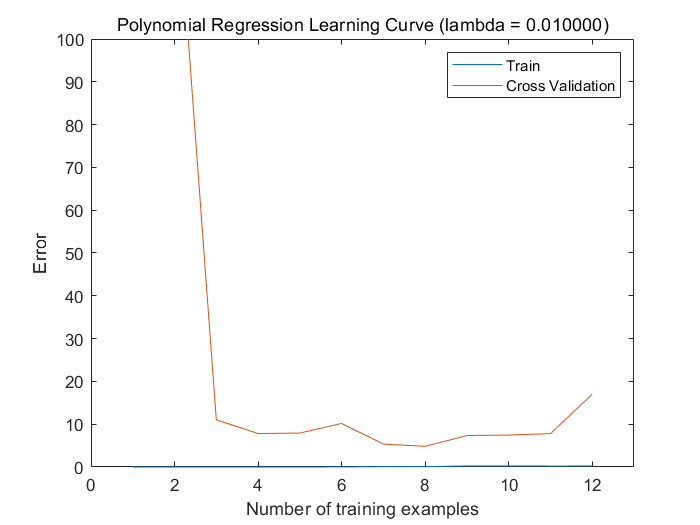

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

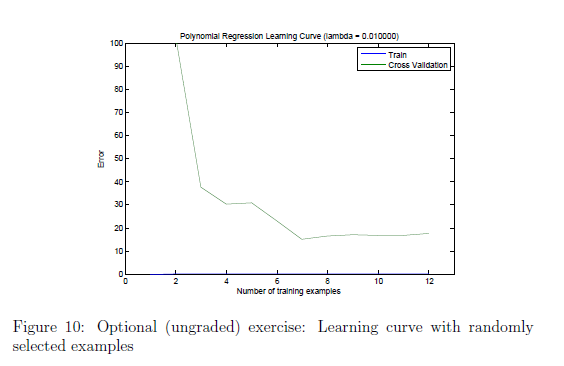

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

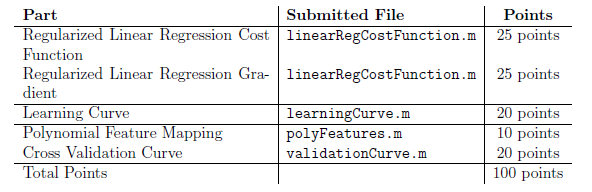

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.